# End of Chapter 2 Problems (MATLAB)

## Q 2.1 a

clear
i = [0.25 0.75 1.25 1.5 2.0]

i =     0.2500    0.7500    1.2500    1.5000    2.0000


V = [-0.45 -0.6 0.7 1.88 6.0]

V =    -0.4500   -0.6000    0.7000    1.8800    6.0000


p1 = polyfit(i,V,1)

p1 =     3.5468   -2.5729


p2 = polyfit(i,V,2)

p2 =     3.3945   -4.0093    0.3886


p3 = polyfit(i,V,3)

p3 =     0.5663    1.4536   -2.1693   -0.0113


p4 = polyfit(i,V,4)

p4 =     0.8869   -3.3844    7.3000   -5.4045    0.4943


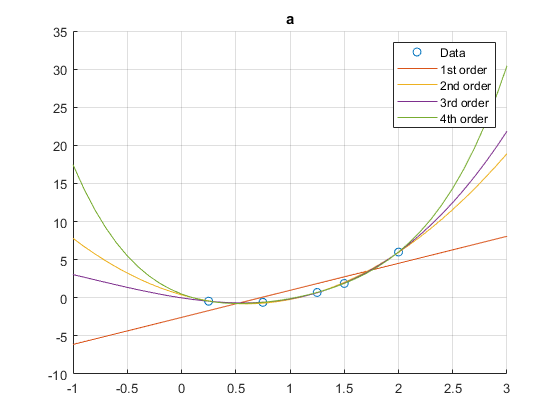

x = -1:0.1:3;

y1 = polyval(p1,x);
y2 = polyval(p2,x);
y3 = polyval(p3,x);
y4 = polyval(p4,x);

scatter(i,V);

hold on
plot(x,y1)
plot(x,y2)
plot(x,y3)
plot(x,y4)
title("a")
grid on
legend("Data", "1st order", "2nd order", "3rd order", "4th order")
hold off

## b

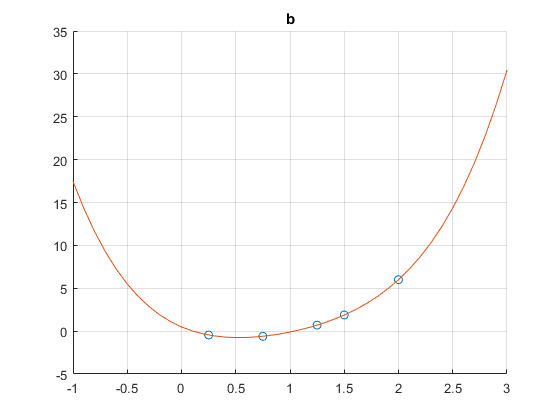

clear y

scatter(i,V)

l = length(x);
y = 1:l;

hold on
grid on

for t=1:1:l
    y(t) = lagrange(x(t),i,V);
end

plot(x,y);
title("b")
hold off

## c

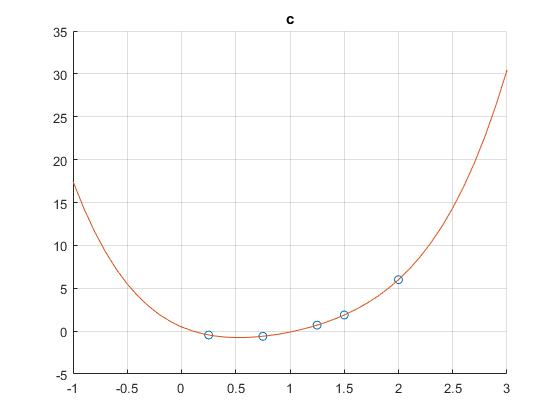

clear y
scatter(i,V);

hold on;
grid on;

y = 1:l;

for t = 1:1:l
    y(t) = NewtonPoly(i,V,x(t));
end

plot(x,y);
title("c")
hold off